# ELABORATO 1 - INTEGRALE

# LO BRUTTO FABIO / MAIONE PAOLO

## DEFINIZIONE DEL PROBLEMA

Si vuole progettare un algoritmo in MPI per risolvere l'integrale definito tra `a` e `b` di una funzione $y=f\left(x\right)$ su p processori.

In particolare si utilizza l'infrastruttura S.C.o.P.E. per permette l'esecuzione del software in un ambiente parallelo.

## DESCRIZIONE DELL'ALGORITMO

In particolare le fasi dell'algoritmo, implementato nel file `elaborato_1.c`, sono:

1) Divisione dell'intervallo $\left\lbrack a\text{ }\text{ }b\right\rbrack$ in `num_intervalli` intervalli e distribuzione di questi ultimi in p processori: ognuno dei p processori calcola l'integrale sul sotto intervallo di ampiezza $h=\frac{\left(b-a\right)}{\mathrm{num}\underline{\text{ }} \mathrm{intervalli}}$ ricevuto dal processo *root* (cioè quello con rank 0);

2) Elaborazione dell'integrale parziale in parallelo con la **formula trapezoidale composita**

                        
$$T_{n+1} \left(f\right)=\frac{h}{2}\text{ }\left(f\left(a\right)+f\left(b\right)+2\text{ }\sum_{i=1}^{n} f\left(a+\mathrm{ih}\right)\right)$$
   

3) Combinazione dei risultati parziali nel processo* root* che determinerà il risultato finale.

A tal proposito sono state utilizzate le primitive fornite da MPI (rispettivamente per la prima fase `MPI_Scatterv()` e per la terza `MPI_Reduce()`).

Inoltre l'algoritmo progettato comprende anche il caso in cui il numero degli intervalli non è multiplo del numero di processori p a disposizione.

Si è scelto di misurare i tempi di esecuzione nel processo di rank 0 usando la primitiva` MPI_Wtime()` tra la fase 2 e la fase 3 scegliendo il minimo tra 3 misurazioni ripetute.

Infine, si osservi che i controlli di robustezza del software sono stati interamente delegati al processo *root*.

## INPUT, OUTPUT E CONDIZIONI DI ERRORE

- **Input**: la funzione $f$ da integrare, i due estremi dell'intervallo` a` e `b`, il numero di intervalli `num_intervalli.`

- **Output**: l'approssimazione dell'integrale definito tra `a` e `b` di $f$.

- **Condizioni di errore**: l'estremo `b` non deve essere minore di `a`, il numero di intervalli deve essere un intero positivo non minore del numero di processori.

## ESEMPIO DI FUNZIONAMENTO

Nell'immagine seguente vi è un esempio di funzionamento con $f\left(x\right)=\frac{x}{x^2 +5}$ ,

con `a=0` e `b=1` e con `num_intervalli = 100000.`

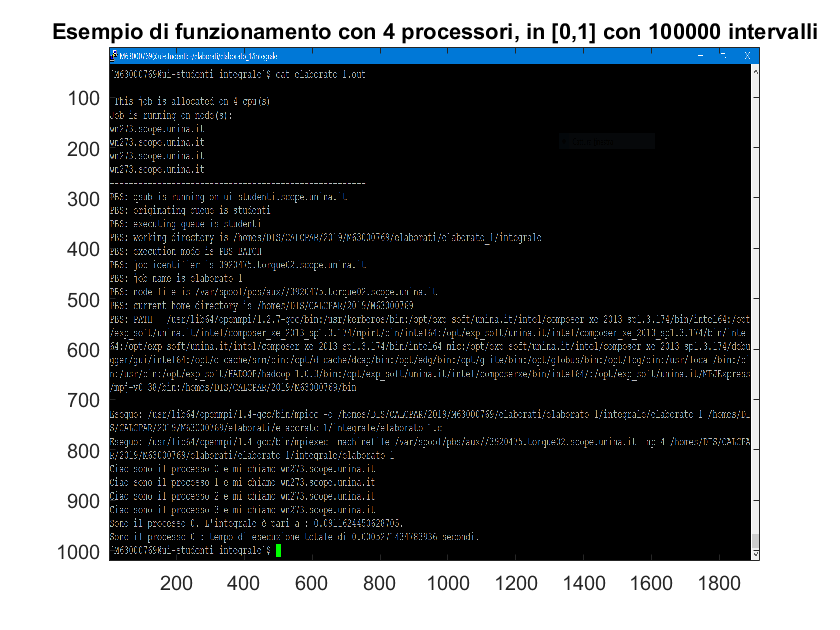

%esempio di funzionamento
funzionamento

## ESEMPI DI ERRORE

Nelle successivi immagini, invece, sono mostrati i messaggi di errore al verificarsi delle condizioni sopra citate.

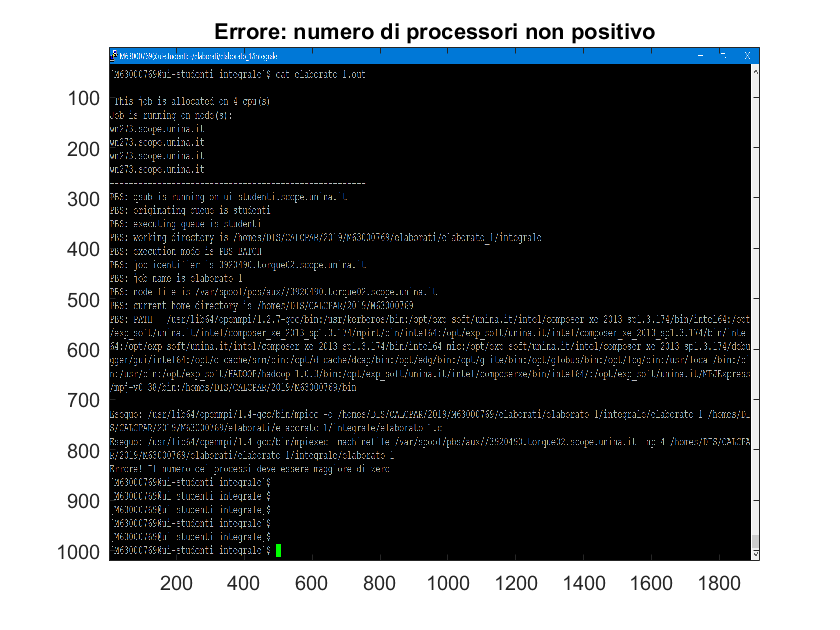

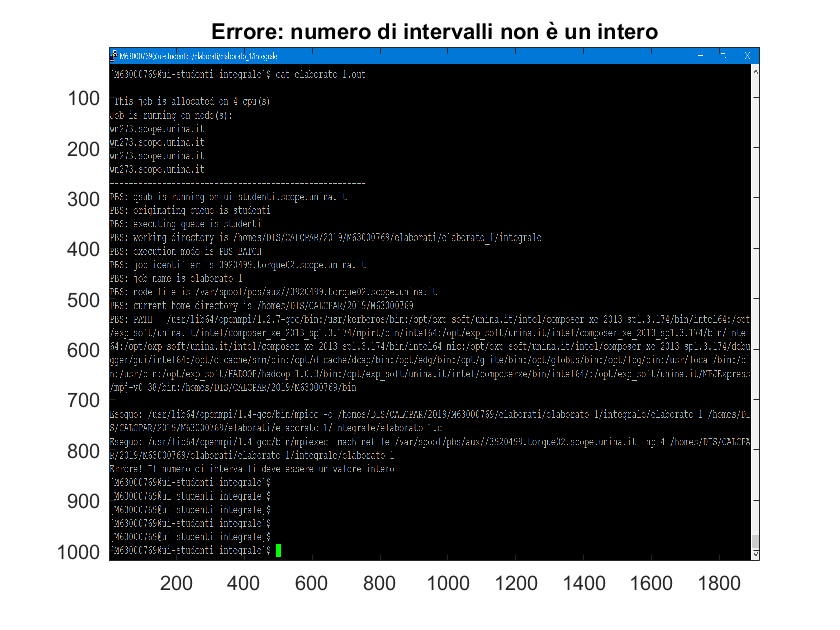

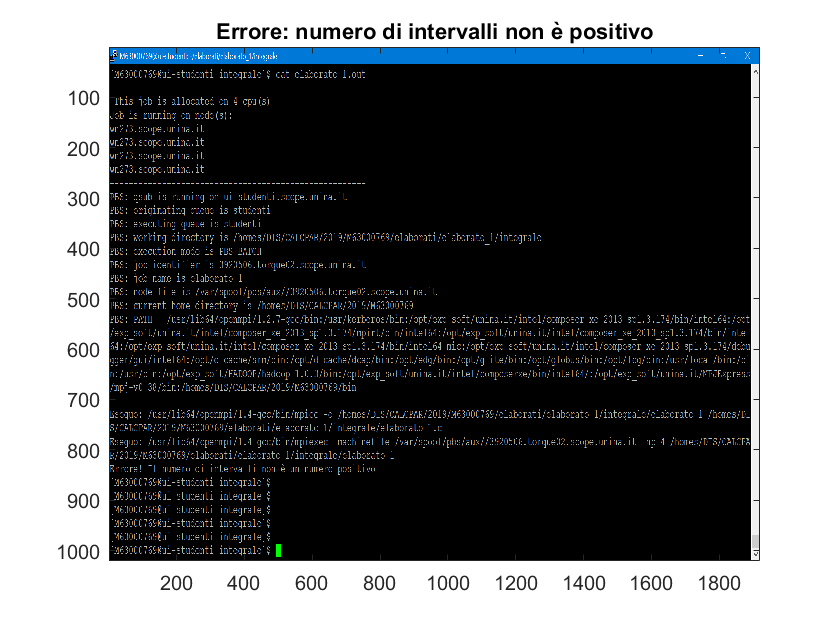

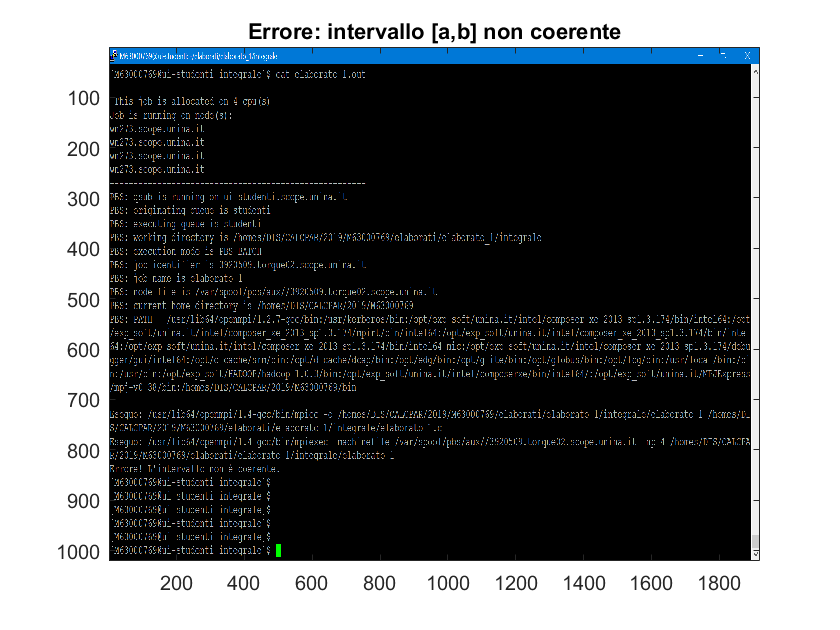

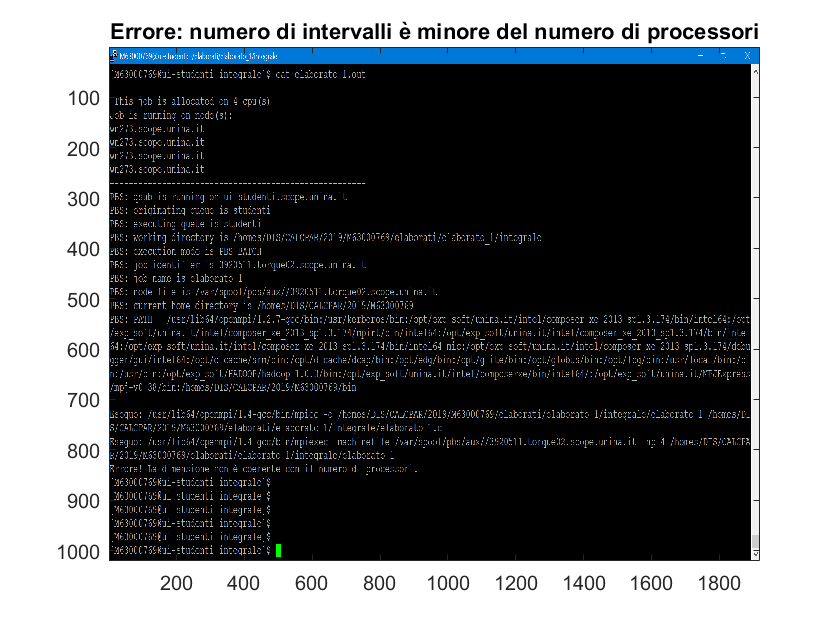

%un esempio per ciascuna condizione di errore
errori

## ANALISI DELLE PRESTAZIONI (T(p), S(p), E(p))

Di seguito per brevità si indicherà con p il numero di processori e con N il numero di intervalli.

## Tempo di esecuzione - T(p)

Si è scelto di misurare i tempi di esecuzione nel processo* root* usando la primitiva `MPI_Wtime()`. In particolare l'intervallo di tempo misurato è quello che comprende le fasi 2 e 3 dell'algoritmo prima citate.

Per ciascuna misurazione (al variare di N da 10k a 100M e al variare di p da 2 a 16) è stato considerato il minimo tra 3 esecuzioni ripetute, eseguite in momenti diversi.

Di seguito si riportano i risultati in forma di tabelle e grafici.

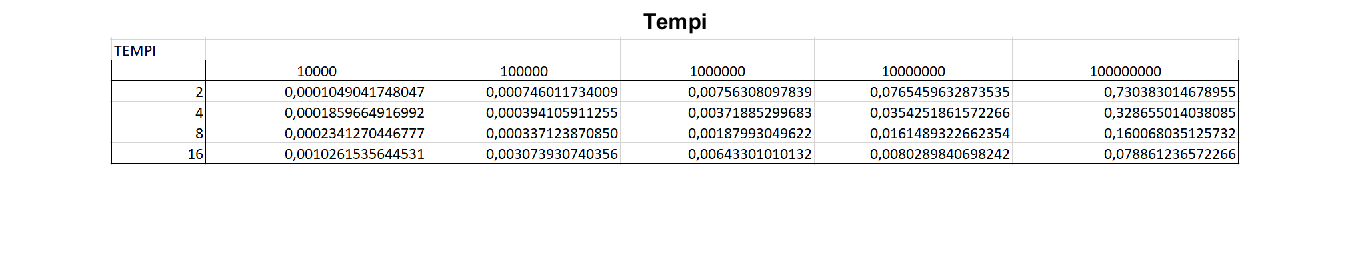

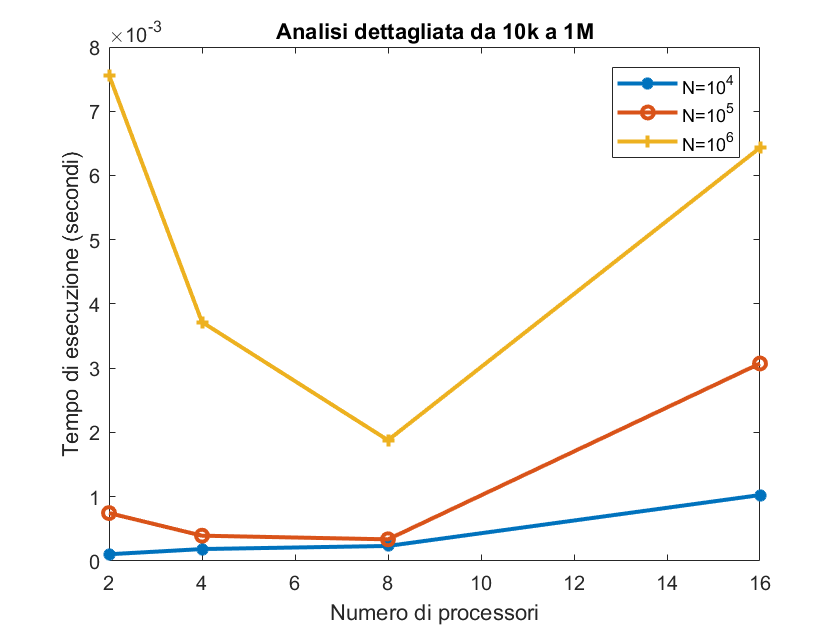

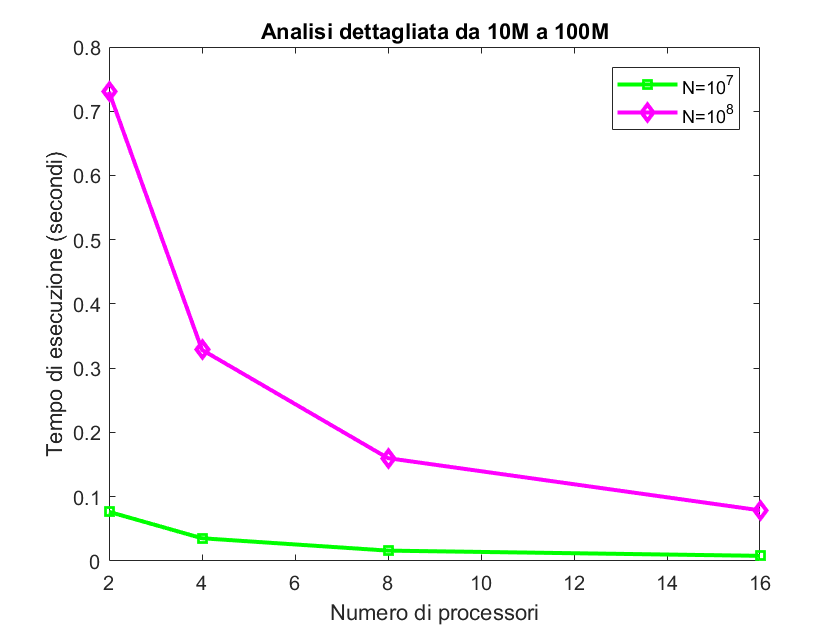

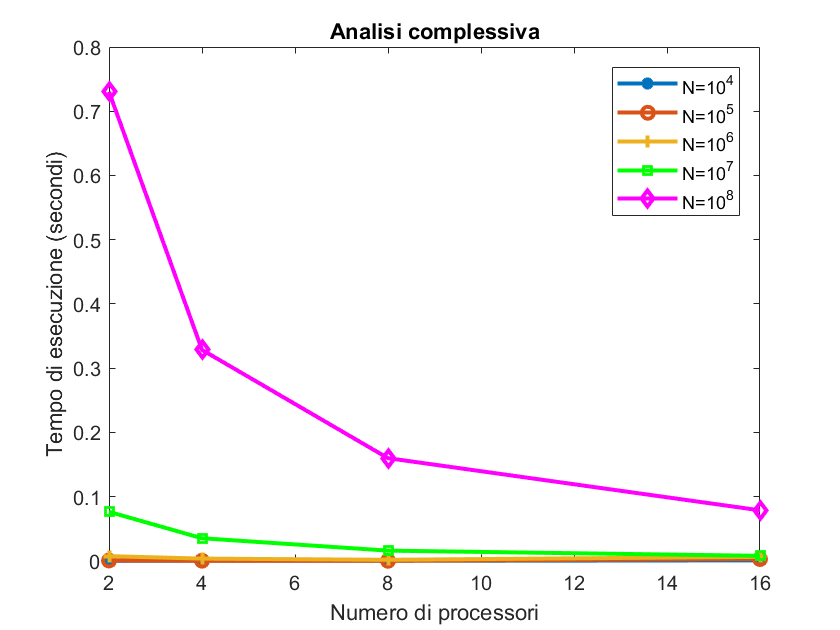

%esecuzione script per tabelle e grafici
tempi

L'ultimo grafico è quello che riassume i risultati ottenuti per tutti i possibili valori di N e p. Sono forniti due ulteriori grafici (i primi due) che mostrano gli andamenti più nel dettaglio.

Per considerazioni più di dettaglio su questi risultati si rimanda alla sezione Conclusioni.

## Speed up ed Efficienza - S(p) ed E(p)

Si è calcolato, inoltre, il tempo di riferimento `T(1)` che corrisponde al tempo di esecuzione su un unico processore.

A partire dai tempi misurati nella sezione precedente e da `T(1)` è stato calcolato lo speed-up al variare di N e p.

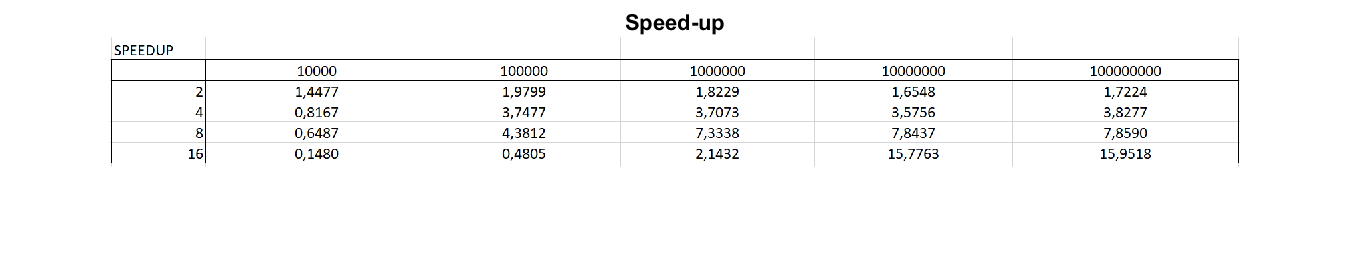

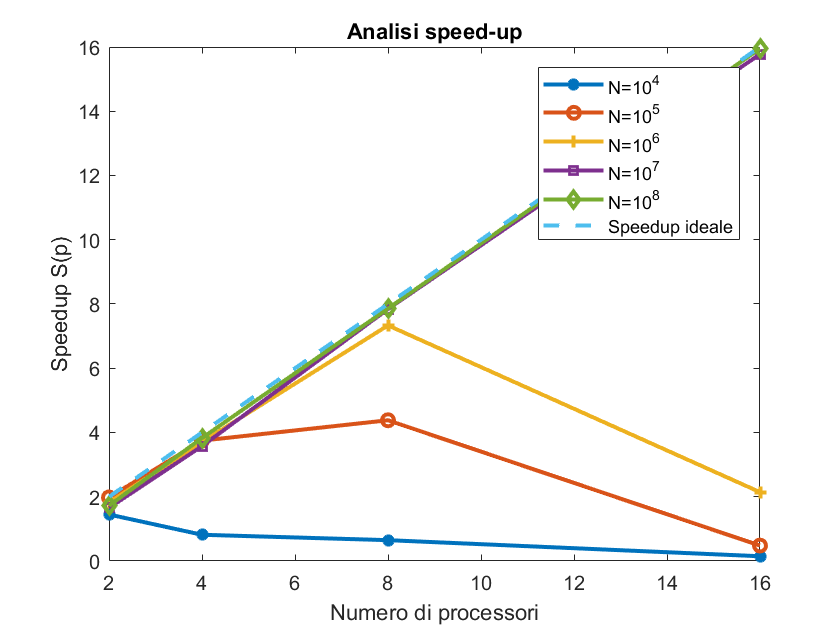

%esecuzione script per tabelle e grafici
speedup

Infine si è calcolata l'efficienza rapportando lo speed up S(p) al numero di processori p.

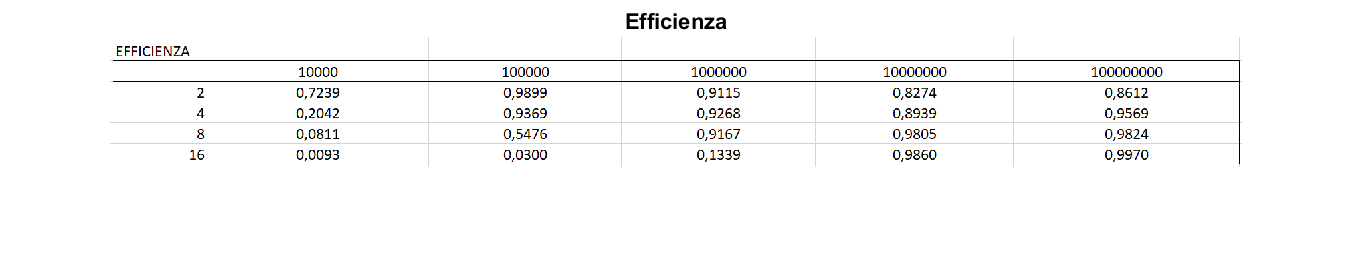

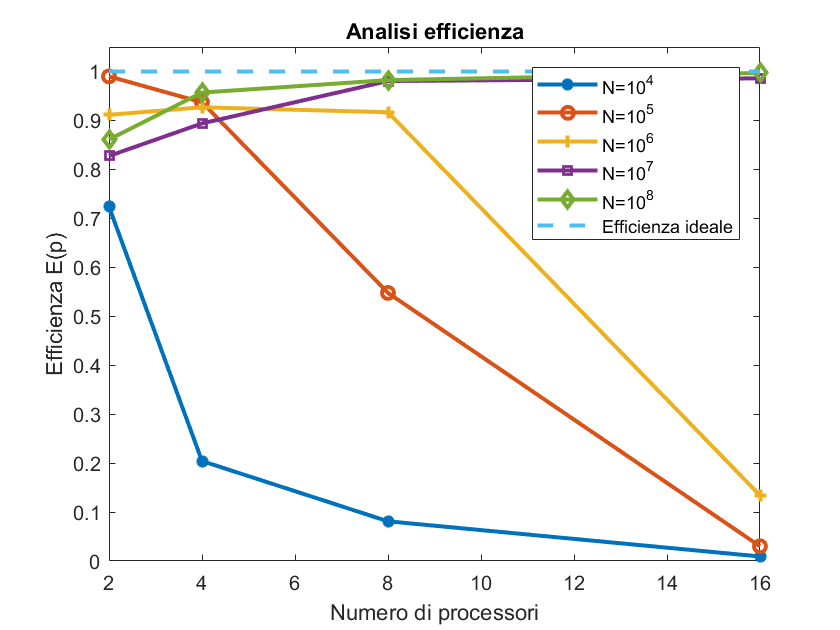

%esecuzione script per tabelle e grafici
efficienza

## Conclusioni

Dai grafici appena presentati si possono trarre alcune considerazioni.

Analizzando l'efficienza si nota come nel caso N=${10}^4$ e N=${10}^5$  l'efficienza ottimale si ha per 2 processori.

Invece nel caso di N=${10}^6$ l'ottimo è in corrispondenza di 4 processori, mentre per N=${10}^7$ e N=${10}^8$ è 16 processori. Ciò può portare a dire che con molta probabilità l'ottimo per 8 processori si trova in corrispondenza di un valore intermedio tra N=${10}^6$ e N=${10}^7$.

Si possono fare ulteriori considerazioni notando che, per N fissato, l'efficienza peggiora dopo un certo valore di p (ciò verifica sperimentalmente la legge di Amdahl), e che, in generale, all'aumentare sia di N che di p, l'efficienza migliora (verificando la legge di Gustafson).

Analoghe considerazioni per i tempi e lo speedup.

## ANALISI DELL' ACCURATEZZA

Confrontando i risultati ottenuti sul cluster Scope e quelli ottenuti su MATLAB si ottengono i seguenti errori relativi. I livelli di accuratezza sono stati misurati fissando a 8 il numero di processori, e facendo variare la dimensione del problema `num_intervalli`. Gli estremi di integrazione scelti sono `a=0 , b=5`.

Per i test è stata usata la seguente funzione integranda:  


$$f\left(x\right)=1+\mathrm{sin}\left(10x\right)\ast \frac{x}{x^2 +5}$$


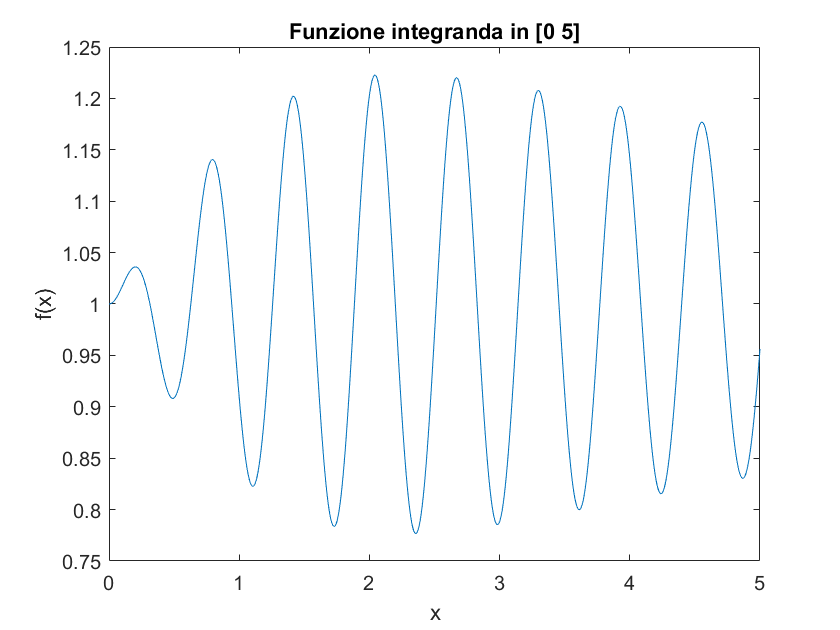

%grafico della funzione integranda
grafico

%esecuzione script per i test di accuratezza
accuratezza

F = function_handle with value:
    @(x)1+sin(10.*x).*(x./(x.^2+5))


risultato_matlab =      4.983979125364205e+00


err_rel_10k_intervalli =      9.594707130727628e-05


err_rel_100k_intervalli =      9.599362810692822e-06


err_rel_1M_intervalli =      9.651938468569100e-07


err_rel_10M_intervalli =      1.017821889124140e-07


err_rel_100M_intervalli =      1.540213007827612e-08
